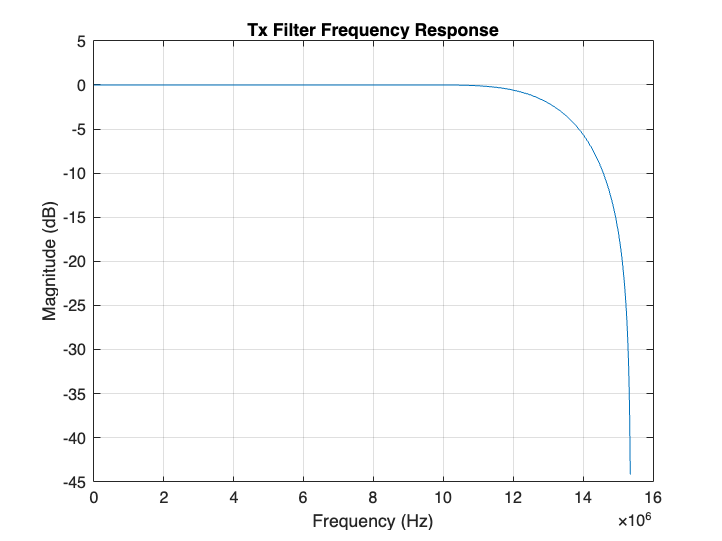

clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMChannel helperOFDMFrequencyOffset clear helperOFDMChannelEstimation
close all;

userParam = struct( ...
    'BWIndex',          5, ...   % Index corresponding to desired bandwidth
    'modOrder',         64, ...   % Subcarrier constellation modulation order
    'codeRateIndex',    0, ...   % Code rate index corresponding to desired rate
    'numSymPerFrame',   15, ...   % Number of OFDM symbols per frame
    'numFrames',        20 ...
    , ...   % Number of frames to be generated for simulation (12-500)
    'fc',               1000000000, ...   % Carrier frequency (Hz)
    'enableFading',     true                 , ...   % Enable/disable channel fading
    'chanVisual',       "Impulse response", ...   % Channel fading visualization option
    'enableCFO',        true                 , ...   % Enable/disable carrier frequency offset compensation
    'enableCPE',        true                 , ...   % Enable/disable common phase error compensation
    'enableScopes',     true                 , ...   % Enable/disable scopes
    'verbosity',        1);      % Diagnostic output verbosity

[sysParam, txParam] = helperOFDMSetParameters(userParam);

[~,codeParam] = helperOFDMGetTables(userParam.BWIndex,userParam.codeRateIndex);
codeRate = codeParam.codeRate; % Coding rate
txObj = helperOFDMTxInit(sysParam);

rng(123)

ssIdx = sysParam.ssIdx;         % sync symbol index
disp(['sync symbol Index: ', mat2str(ssIdx)])

sync symbol Index: 1



rsIdx = sysParam.rsIdx;         % reference symbol index
disp(['reference symbol Index: ', mat2str(rsIdx)])

reference symbol Index: 2



headerIdx = sysParam.headerIdx; % header symbol index
disp(['header symbol Index: ', mat2str(headerIdx)])

header symbol Index: 3



numCommonChannels = length(ssIdx) + length(rsIdx) + length(headerIdx);
disp(['Number of common channel symbols: ', num2str(numCommonChannels)])

Number of common channel symbols: 3



fftLen = sysParam.FFTLen;   % FFT length
disp(['FFT length: ', num2str(fftLen)])

FFT length: 2048



cpLen  = sysParam.CPLen;    % CP length
disp(['Cyclic Prefix length: ', num2str(cpLen)])

Cyclic Prefix length: 512



numSubCar = sysParam.usedSubCarr; % Number of subcarriers per OFDM symbol
disp(['Number of subcarriers: ', num2str(numSubCar)])

Number of subcarriers: 1200



numSymPerFrame = sysParam.numSymPerFrame; % Number of OFDM symbols per frame
disp(['Number of OFDM symbols per frame: ', num2str(numSymPerFrame)])

Number of OFDM symbols per frame: 15


grid = zeros(numSubCar,numSymPerFrame);
%1200 x 15
txParamConfig = txParam

txParamConfig = struct with fields:
         modOrder: 64
    codeRateIndex: 0



% Derive actual parameters from inputs
[modType,bitsPerModSym,puncVec,~] = ...
    getParameters(txParamConfig.modOrder,txParamConfig.codeRateIndex);
disp(['ModType: ', num2str(modType)])

ModType: 64QAM


disp(['bits per modsym: ', num2str(bitsPerModSym)])

bits per modsym: 6


disp(['puncVec: ', num2str(puncVec)])

puncVec: 1  1


%% Synchronization signal generation
syncSignal = helperOFDMSyncSignal();
syncSignalInd = (numSubCar/2) - 31 + (1:62);
disp(['syncsigInd: ', num2str(syncSignalInd)])

syncsigInd: 570  571  572  573  574  575  576  577  578  579  580  581  582  583  584  585  586  587  588  589  590  591  592  593  594  595  596  597  598  599  600  601  602  603  604  605  606  607  608  609  610  611  612  613  614  615  616  617  618  619  620  621  622  623  624  625  626  627  628  629  630  631



% Load synchronization signal on the grid
grid(syncSignalInd,ssIdx) = syncSignal;

%% Reference signal generation
refSignal = helperOFDMRefSignal(numSubCar);
refSignalInd = 1:length(refSignal);

% Load reference signals on the grid
grid(refSignalInd,rsIdx(1)) = refSignal;



FFTLenIndex = 5;         
modTypeIndex = 3;        
codeRateIndex = 0;       


FFTLenIndexBits     = [true false true];   % '101'
modTypeIndexBits    = [false true true];   % '101'
codeRateIndexBits   = [false false];       % '00'

% Pad with zeros to make 14 total bits
reserveBits = zeros(1, 14 - 3 - 3 - 2);     % 14 - FFTLenBits - ModBits - CodeRateBits

% Combine all bits
headerBits = [FFTLenIndexBits, modTypeIndexBits, codeRateIndexBits, reserveBits];

diagnostics.headerBits = headerBits.';

  

%Cyclic redundancy check
% indirect with no bit reversal

% headerbits len = 14
% 1010 1100 0000 00

% P(x) = x^16 +x^12 + x^5 + 1
% 1000 1000 0001 0000 1

% header + 16 zeros [0, 0, 0, 0 ...]
% divide by polynomial and get a remainder, append to og header
% rem =  1, 1, 0, 1, 1, 0, 1, 0, 0, 0, 0, 1, 1, 1, 0, 0



% disp(crcGenerate(headerBits',txObj.crcHeaderGen))
% Append CRC bits
headerCRCOut = reshape(crcGenerate(headerBits',txObj.crcHeaderGen),1,[]);

disp(headerCRCOut)

     1     0     1     0     1     1     0     0     0     0     0     0     0     0     1     1     0     1     1     0     1     0     0     0     0     1     1     1     0     0



% Perform convolutional coding
headerConvK = sysParam.headerConvK; 
disp(['headerconvK: ', num2str(headerConvK)])

headerconvK: 7



% looks at current bit and previous 6 bits
% depth memory of encoder = 7

headerConvCode = sysParam.headerConvCode; 
disp(['headerConvCode: ', num2str(headerConvCode)])

headerConvCode: 171  133



% octal to decimal

% [171] = 1 * 8^2 + 7 * 8 + 1 = 64 + 56 + 1 = 121
% [133] = 1 * 8^2 + 3 * 8 + 3 = 64 + 24 + 3 = 91

% Decimal to binary
% [171][121] = 1111001
% [131][91] =  1011011

% using bits  1, 2, 3, 4, 7
% using bits  1, 3, 4, 6, 7


trellis_structure = poly2trellis(headerConvK,headerConvCode)

trellis_structure = struct with fields:
     numInputSymbols: 2
    numOutputSymbols: 4
           numStates: 64
          nextStates: [64×2 double]
             outputs: [64×2 double]


% input symbols 2 -----> out symbols 4
% # of states 64 

headerConvOut = convenc([headerCRCOut, zeros(1,headerConvK-1)], ...
    poly2trellis(headerConvK,headerConvCode)); % Terminated Mode

% appends 6 zeros (to terminate?)

%EXAMPLE 

MSG = [1, 0, 1]

MSG =      1     0     1


% Termiate [101000000]
% G1 = 1, 2, 3, 4, 7
% G2 = 1, 3, 4, 6, 7

testConv = convenc([MSG, zeros(1,headerConvK-1)], ...
    poly2trellis(headerConvK,headerConvCode));

disp(testConv)

     1     1     1     0     0     0     0     1     1     1     1     0     1     1     0     1     1     1



% 11 10 00 01 11 10 11 01 11

% [100000000]
% 1 + 0 + 0 + 0 + 0 mod 2 = 1
% 1 + 0 + 0 + 0 + 0 mod 2 = 1
% [1, 1]

% [010000000]
% 0 + 1 + 0 + 0 + 0 mod 2 = 1
% 0 + 0 + 0 + 0 + 0 mod 2 = 0

% [101000000]
% 1 + 0 + 1 + 0 + 0 mod 2 = 0
% 1 + 1 + 0 + 0 + 0 mod 2 = 0

% [010100000]
% 0 + 1 + 0 + 1 + 0 mod 2 = 0
% 0 + 0 + 1 + 0 + 0 mod 2 = 1

% WORKING for first 4 bits




disp(['headerconvOut: ', num2str(headerConvOut)])

headerconvOut: 1  1  1  0  0  0  0  1  0  0  1  1  1  0  0  1  0  0  0  1  1  0  1  1  0  0  0  0  1  1  0  1  0  1  1  1  1  0  0  0  0  1  1  0  1  0  0  1  1  1  1  0  1  0  1  0  1  0  0  0  1  0  1  0  1  0  1  1  0  0  0  0


disp(length(headerConvOut))

    72




% after convolutional coding, 72 bits

% Perform Interleaving
headerIntrlvLen = sysParam.headerIntrlvNColumns;
disp(['headerIntrlvLen: ', num2str(headerIntrlvLen)])

headerIntrlvLen: 12



headerIntrlvOut = reshape(reshape(headerConvOut,headerIntrlvLen,[]).',[],1);

disp(['headerIntrlvOut: ', num2str(headerIntrlvOut.')])

headerIntrlvOut: 1  1  0  1  1  1  1  0  0  0  1  0  1  0  0  0  1  1  0  1  0  0  0  0  0  0  1  0  1  1  0  0  1  1  0  0  0  0  0  1  1  1  1  1  1  0  0  1  0  1  0  1  1  0  0  0  1  0  0  0  1  1  1  0  0  0  1  1  1  1  0  0


disp(length(headerIntrlvOut))

    72




% 6 bits 12 columns 
% rearrange to prevent burst
% 12 x 6 
% we transpose to get to 
% 6 x 12
% flatten back to original shape


% Modulate header using BPSK
headerSym = pskmod(headerIntrlvOut,2,InputType="bit");


% BPSK mod into -1 or 1
% they are pi radians part in phase
% c = cos(2pi (fc * t))
% s = exp(j* (2pi * b/2))
% if b = 0, exp (j0) = 1
% if b = 1, exp (jpi)= -1



disp(['headerSym: ', num2str(headerSym.')])

headerSym: -1+1.2246e-16i           -1+1.2246e-16i                     1+0i           -1+1.2246e-16i           -1+1.2246e-16i           -1+1.2246e-16i           -1+1.2246e-16i                     1+0i                     1+0i                     1+0i           -1+1.2246e-16i                     1+0i           -1+1.2246e-16i                     1+0i                     1+0i                     1+0i           -1+1.2246e-16i           -1+1.2246e-16i                     1+0i           -1+1.2246e-16i                     1+0i                     1+0i                     1+0i                     1+0i                     1+0i                     1+0i           -1+1.2246e-16i                     1+0i           -1+1.2246e-16i           -1+1.2246e-16i                     1+0i                     1+0i           -1+1.2246e-16i           -1+1.2246e-16i                     1+0i                     1+0i                     1+0i                     1+0i                     1+0i           -1+1.2246e-16i

headerSymInd = (numSubCar/2)-36+(1:72);

% Load header signal on the grid
grid(headerSymInd,headerIdx) = headerSym;


%% Pilot generation
% Number of data/pilots OFDM symbols per frame
numDataOFDMSymbols = numSymPerFrame - numCommonChannels;
pilot    = helperOFDMPilotSignal(sysParam.pilotsPerSym);    % Pilot signal values
pilot    = repmat(pilot,1,numDataOFDMSymbols);              % Pilot symbols per frame
pilotGap = sysParam.pilotSpacing;                           % Pilot signal repetition gap in OFDM symbol
pilotInd = (1:pilotGap:numSubCar).';

disp(pilot)

     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1
    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
     1     1     1     1     1     1     1     1     1     1     1     1
    -1    -1    -1    -1    -1    -1    -1    -1   

disp(['pilot spacing: ', num2str(pilotGap)])

pilot spacing: 24


disp(['pilot ind: ', num2str(pilotInd.')]) % 50 x 1

pilot ind: 1    25    49    73    97   121   145   169   193   217   241   265   289   313   337   361   385   409   433   457   481   505   529   553   577   601   625   649   673   697   721   745   769   793   817   841   865   889   913   937   961   985  1009  1033  1057  1081  1105  1129  1153  1177



%% Data generation
% Initialize convolutional encoder parameters
dataConvK = sysParam.dataConvK;
dataConvCode = sysParam.dataConvCode;

% Calculate transport block size
trBlkSize = sysParam.trBlkSize; 
disp(['trBlkSize: ', num2str(trBlkSize)])

trBlkSize: 41362



if (~isfield(txParamConfig,{'txDataBits'})) || ...
        isempty(txParamConfig.txDataBits)
    % Generate random bits if txDataBits is not a field
    txParamConfig.txDataBits = randi([0 1],trBlkSize,1);
else
    % Pad appropriate bits if txDataBits is less than required bits
    if length(txParamConfig.txDataBits) < trBlkSize
        if isrow(txParamConfig.txDataBits)
            txParamConfig.txDataBits = ...
                [txParamConfig.txDataBits zeros(1,trBlkSize-length(txParamConfig.txDataBits))];
        else
            txParamConfig.txDataBits = ...
                [txParamConfig.txDataBits ; zeros((trBlkSize-length(txParamConfig.txDataBits)),1)];
        end
    end
end

diagnostics.dataBits = txParamConfig.txDataBits(1:trBlkSize);

% Retrieve data to form a transport block
dataBits = txParamConfig.txDataBits;
if isrow(dataBits)
    dataBits = dataBits.';
end

% 41362 databits

% Append CRC bits to data bits
crcData = crcGenerate(dataBits, txObj.crcDataGen);
disp(['crcData: ', num2str(crcData.')])

crcData: 1  0  0  1  1  0  1  1  0  0  0  1  0  0  0  1  0  0  1  1  1  1  1  1  1  0  0  0  0  1  0  0  0  0  0  0  0  1  1  1  1  0  0  0  1  0  0  1  1  1  0  1  1  1  0  0  0  1  1  1  1  1  1  1  1  0  1  0  0  1  0  1  1  1  0  1  1  0  0  1  0  1  1  0  1  1  0  0  0  0  1  1  0  1  1  1  0  0  0  0  1  1  0  0  0  1  1  1  1  0  0  0  0  1  0  1  1  1  0  1  1  0  0  1  1  1  0  1  1  0  1  0  1  1  1  0  0  0  0  1  0  0  1  1  0  1  1  0  1  1  0  1  0  0  1  0  1  1  1  0  0  1  1  0  1  1  0  1  1  1  1  0  1  1  1  0  0  0  0  0  1  0  0  1  0  1  0  1  1  1  0  1  0  1  0  1  0  1  0  0  1  0  1  1  1  1  0  1  1  0  1  1  0  1  0  0  0  0  1  0  0  1  0  1  1  0  0  1  0  0  0  0  0  1  1  0  0  1  1  1  0  0  1  0  0  0  1  0  1  1  0  0  1  0  0  1  1  1  0  0  1  0  1  0  0  0  0  0  0  1  0  0  0  0  1  0  1  0  1  0  1  0  0  1  0  1  1  1  1  1  0  1  0  1  0  1  1  1  0  1  0  1  0  0  0  1  0  1  1  0  1  1  0  0  0  1  1  1  1  1  0  0  1  0  0  0  0  1  0  1  1

% polynomial : [32 26 23 22 16 12 11 10 8 7 5 4 2 1 0]
% binary : [1 0 0 0 0 0 1 0 0 1 1 0 0 0 0 0 1 0 0 0 1 1 1 0 1 1 0 1 1 0 1 1 1]

%
% 
% bits + 32 bits = 41394

% pnSeq
% linear feedback shift register
x=(txObj.pnSeq(sysParam.initState).')

x =      0     1     1     0     1     1     0     0     0     0     0     1     1     0     0     1     1     0     1     0     1     0     0     1     1     1     0     0     1     1     1     1     0     1     1     0     1     0     0     0     0     1     0     1     0     1     0     1     1     1


disp(x)

  Columns 1 through 5461

     0     1     1     0     1     1     0     0     0     0     0     1     1     0     0     1     1     0     1     0     1     0     0     1     1     1     0     0     1     1     1     1     0     1     1     0     1     0     0     0     0     1     0     1     0     1     0     1     1     1     1     1     0     1     0     0     1     0     1     0     0     0     1     1     0     1     1     1     0     0     0     1     1     1     1     1     1     1     0     0     0     0     1     1     1     0     1     1     1     1     0     0     1     0     1     1     0     0     1     0     0     1     0     0     0     0     0     0     1     0     0     0     1     0     0     1     1     0     0     0     1     0     1     1     1     0     1     0     1     1     0     1     1     0     0     0     0     0     1     1     0     0     1     1     0     1     0     1     0     0     1     1     1     0     0     1     1     1     1     0     1     1  

% comm.PNSequence

% initstate = [1 0 1 1 1 0 1]
% pnseq x^-7 + x^-3 + 1
% pnmask = [0 0 0 1 0 0 1]


% Additively scramble using scramble polynomial
scrOut = xor(crcData,txObj.pnSeq(sysParam.initState));
disp(['srcOut: ', num2str(scrOut.')])

srcOut: 1  1  1  1  0  1  1  1  0  0  0  0  1  0  0  0  1  0  0  1  0  1  1  0  0  1  0  0  1  0  1  1  0  1  1  0  1  1  1  1  1  1  0  1  1  1  0  0  0  0  1  0  1  0  0  0  1  1  0  1  1  1  0  0  1  1  0  1  0  1  0  0  0  0  1  0  0  1  0  1  0  1  0  1  0  1  1  1  1  1  1  1  1  1  0  0  0  0  1  0  1  0  0  0  0  1  1  1  0  0  0  0  1  1  0  0  0  1  0  1  0  0  1  0  0  1  1  1  0  1  1  1  0  1  1  0  0  0  1  0  0  0  0  0  0  0  1  1  1  1  1  0  1  0  1  1  0  0  0  0  1  0  1  1  1  1  0  1  0  1  0  0  0  1  0  1  1  1  1  0  0  0  0  0  0  0  0  1  1  0  1  1  1  0  1  1  0  1  1  1  0  1  0  0  0  1  0  1  1  1  0  0  0  0  1  1  1  0  1  1  0  0  1  1  1  1  0  1  1  0  0  0  0  1  1  1  0  1  1  0  0  0  0  1  0  0  1  1  1  0  1  1  1  1  0  0  0  1  1  1  1  0  1  0  0  1  1  0  0  0  1  0  1  0  0  0  1  1  0  1  1  0  1  0  1  0  1  0  0  1  1  1  0  1  0  0  1  0  0  0  0  0  1  1  1  0  0  0  1  0  0  1  1  0  0  1  0  0  1  0  1  1  1  0  0  1  1  0  1  0  0 


% Perform convolutional coding
dataEnc = convenc([scrOut;zeros(dataConvK-1,1)], ...
    poly2trellis(dataConvK,dataConvCode),puncVec); % Terminated mode
dataEnc = [dataEnc; zeros(sysParam.trBlkPadSize,1)]; % append pad to factorize payload length
dataEnc = reshape(dataEnc,[],numDataOFDMSymbols); % form columns of symbols

% same as before with 7 , [171, 133]
%should result in double the bits (82800)


% Perform interleaving and symbol modulation
modData   = zeros(numel(dataEnc)/(numDataOFDMSymbols*bitsPerModSym),numDataOFDMSymbols);
for i = 1:numDataOFDMSymbols
    % Interleave each symbol
    intrlvOut = OFDMInterleave(dataEnc(:,i),sysParam.dataIntrlvNColumns);
    
    %6900 / 6 bits per symbol = 1150

    % Modulate the symbol
    modData(:,i) = qammod(intrlvOut,txParamConfig.modOrder,...
        UnitAveragePower=true,InputType="bit");
end
modDataInd = 1:numSubCar;

% Remove the pilot indices from modData indices
modDataInd(pilotInd) = [];

% Load data and pilots on the grid
grid(pilotInd,(headerIdx+1:numSymPerFrame)) = pilot;
grid(modDataInd,(headerIdx+1:numSymPerFrame)) = modData;
    



%% OFDM modulation
dcIdx = (fftLen/2)+1;
% dc at 1025
disp(['dcIdx: ', num2str(dcIdx)])

dcIdx: 1025



% Generate sync symbol
nullLen = (fftLen - 62)/2;
syncNullInd = [1:nullLen dcIdx fftLen-nullLen+2:fftLen].';
ofdmSyncOut = ofdmmod(syncSignal,fftLen,cpLen,syncNullInd);

% Generate reference symbol
nullInd = [1:((fftLen-numSubCar)/2) dcIdx ((fftLen+numSubCar)/2)+1+1:fftLen].';
ofdmRefOut  = ofdmmod(refSignal,fftLen,cpLen,nullInd);
disp(['nulls: ', num2str(nullInd.')])

nulls: 1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149   150   151   152   153   154   155   156   157   158   159   160   161   162   163   164   165   166  


% 1-424, 1025 , 1626-2048]

% Generate header symbol
nullLen = (fftLen - 72)/2;
headerNullInd = [1:nullLen dcIdx fftLen-nullLen+2:fftLen].';
ofdmHeaderOut = ofdmmod(headerSym,fftLen,cpLen,headerNullInd);

% Generate data symbols with embedded pilot subcarriers
ofdmDataOut = ofdmmod(modData,fftLen,cpLen,nullInd,sysParam.pilotIdx,pilot);
ofdmModOut = [ofdmSyncOut; ofdmRefOut; ofdmHeaderOut; ofdmDataOut];

% Filter OFDM modulator output
txWaveform = txObj.txFilter(ofdmModOut);

% Collect diagnostic information
diagnostics.ofdmModOut = txWaveform.';


function [modType,bitsPerModSym,puncVec,codeRate] = getParameters(modOrder,codeRateIndex)
% Select modulation type and bits per modulated symbol
switch modOrder
    case 2
        modType = 'BPSK';
        bitsPerModSym  = 1;
    case 4
        modType = 'QPSK';
        bitsPerModSym  = 2;
    case 16
        modType = '16QAM';
        bitsPerModSym  = 4;
    case 64
        modType = '64QAM';
        bitsPerModSym  = 6;
    case 256
        modType = '256QAM';
        bitsPerModSym  = 8;
    case 1024
        modType = '1024QAM';
        bitsPerModSym  = 10;
    otherwise
        modType = 'QPSK';
        bitsPerModSym  = 2;
        fprintf('\n Invalid modulation order. By default, QPSK is applied. \n');
end

% Select puncture vector and punctured code rate
switch codeRateIndex
    case 0
        puncVec = [1 1];
        codeRate = 1/2;
    case 1
        puncVec = [1 1 0 1];
        codeRate = 2/3;
    case 2
        puncVec = [1 1 1 0 0 1];
        codeRate = 3/4;
    case 3
        puncVec = [1 1 1 0 0 1 1 0 0 1];
        codeRate = 5/6;
    otherwise
        puncVec = [1 1];
        codeRate = 1/2;
        fprintf('\n Invalid code rate. By default, 1/2 code rate is applied. \n');
end
end

function intrlvOut = OFDMInterleave(in,dataIntrlvLen)

lenIn = size(in,1);
numIntRows = ceil(lenIn/dataIntrlvLen);
numInPad = (dataIntrlvLen*numIntRows) - lenIn;  % number of padded entries needed to make the input data length factorable
numFullCols = dataIntrlvLen - numInPad;
inPad = [in ; zeros(numInPad,1)];               % pad the input data so it is factorable
temp = reshape(inPad,dataIntrlvLen,[]).';       % form interleave matrix
temp1 = reshape(temp(:,1:numFullCols),[],1);    % extract out the full rows
if numInPad ~= 0
    temp2 = reshape(temp(1:numIntRows-1,numFullCols+1:end),[],1); % extract out the partially-filled rows
else
    temp2 = [];
end
intrlvOut = [temp1 ; temp2]; % concatenate the two rows


end